### Define LSTM Network Architecture

**Description**: In this section we define the LSTM network architecture as follows

- The input layer which takes each cell element, accordingly the number of features is 1. 

- Specify three bidirectional LSTM layer with L(channel memory) hidden units, and output the complete sequence.

- Include a fully connected layer with an output size that matches the number of responses (output layer)

-  Sigmoid layer to evaluate the PMF per bit in the array

-  Regression layer to compute the half-mean-squared-error loss for regression tasks.

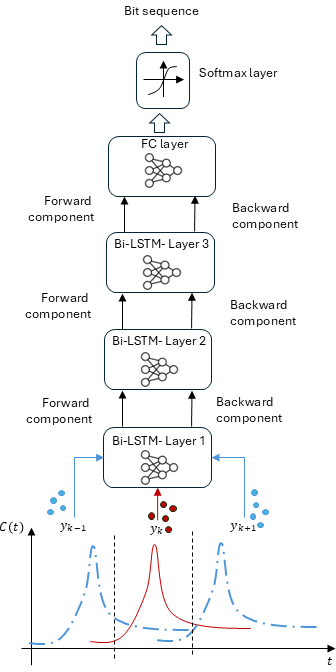

Fig. 2: Network architecture as follows from [3] and [4].

numHiddenUnits = L+1;
numFeatures = 1;
numResponses = 1;    % Output is either 0 or 1 (binary classification)

% Define the BiRNN layers
layers = [ ...
    sequenceInputLayer(numFeatures)                 % Input layer for sequences
    bilstmLayer(numHiddenUnits, 'OutputMode', 'sequence') % Bidirectional LSTM
    bilstmLayer(numHiddenUnits, 'OutputMode', 'sequence') % Bidirectional LSTM
    bilstmLayer(numHiddenUnits, 'OutputMode', 'sequence') % Bidirectional LSTM
    fullyConnectedLayer(numResponses)               % Fully connected layer
    sigmoidLayer                                    % Sigmoid to predict 0 or 1
    regressionLayer];                               % Regression layer


Specify the training options. Train using the Adam solver with a learn rate of 0.001 and a gradient threshold of 1. Set the maximum number of epochs to 200 and disable shuffling. The software, by default, trains on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

% Training options
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 10, ...     % Process one sequence at a time
    'InitialLearnRate', 0.001, ...
    'GradientThreshold', 1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

Error using categorical
Could not find unique values in DATA using the UNIQUE function.

Caused by:
    Error using matlab.internal.math.uniqueCellstrHelper
    Cell array input must be a cell array of character vectors.

### References

[1] P. Hofmann, J. Torres Gómez, F. Dressler, and F. H. P. Fitzek, “Testbed-based Receiver Optimization for SISO Molecular Communication Channels,” in 5th IEEE International Balkan Conference Communications and Networking (BalkanCom 2022), Sarajevo, Bosnia and Herzegovina: IEEE, Aug. 2022, pp. 120–125.

[2] Pit Hofmann, Jorge Torres Gómez, Frank H. P. Frank H.P. , Falko Dressler, April 27, 2023, "Dataset for Macroscale Molecular Communication Testbed", IEEE Dataport, doi: [https://dx.doi.org/10.21227/ytkm-xp81.](https://dx.doi.org/10.21227/ytkm-xp81.)

[3] N. Farsad and A. Goldsmith, “Detection Algorithms for Communication Systems Using Deep Learning,” arXiv, cs.LG, Jul. 2017.

[4] N. Farsad and A. Goldsmith, “Sliding Bidirectional Recurrent Neural Networks for Sequence Detection in Communication Systems,” in IEEE International Conference on Acoustics, Speech and Signal Processing (ICASSP 2018), Calgary, Canada: IEEE, Apr. 2018.